%% Projeto Computacional
% Primeira estrutura de discretização

clear
clc
close all

# 1. Parâmetros físicos

Lx = 1;             % largura [m]
Ly = 1;             % comprimento [m]
Lz = 1;             % altura [m]
rho = 917;          % densidade do gelo [kg/m3]
cp = 2100;          % Calor específico do gelo [J/(kg.K)]
k = 2.22;           % condutividade térmica do gelo [W/(m⋅K)]
T0 = -10;           % Temperatura inicial do gelo [°C]
Tamb = 20;          % Temperatura do ambiente [°C]
l = 334000;         % Calor latente [J/kg]
h = 15;             % Coeficiente de convecçao de 15-25 [W/(m^2⋅K)]
delta_T = 273.15;   % intervalo numérico de transição de fase [K]

# 2.Domínio computacional

Nx = 10;            % numero de pontos no eixo x
Ny = 10;            % numero de pontos no eixo y
Nz = 10;            % numero de pontos no eixo z
delta_x = 0.1;      % intervalo entre pontos em x
delta_y = 0.1;      % intervalo entre pontos em y
delta_z = 0.1;      % intervalo entre pontos em z
delta_t = 0.1;      % intervalo temporal
t0 = 0;             % instante inicial
tf = 15;            % instante final
t = t0:delta_t:tf;  % vetor de pontos no dominio do tempo

# 3.Geração da malha

Inicialmente: Malha uniforme

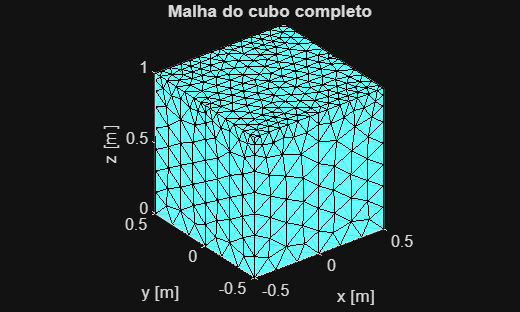

Altura: 1.00 m


Largura: 1.00 m


Comprimento: 1.00 m


model = createpde();

geo = multicuboid(0.5, 0.5, 1);
model.Geometry = geo;

%% 2. IDs da face, arestas e vertices superiores
topFace = 2;
topEdges = [7];
topVertices = [6 7];

%% 3. Gerar a malha refinada
mesh = generateMesh(model, ...
    'Hmax', 0.15, ...
    'Hmin', 0.04, ...
    'Hface', {topFace, 0.08}, ...
    'Hedge', {topEdges, 0.06}, ...
    'Hvertex', {topVertices, 0.04}, ...
    'Hgrad', 1.5, ...
    'GeometricOrder', 'linear');

%% Espelhar a malha para formar o cubo completo

nodes = mesh.Nodes;
elements = mesh.Elements;

N = size(nodes,2);
E = size(elements,2);

% multicuboid está centrado na origem
% Deslocar para x=[0,0.5], y=[0,0.5], z=[0,1]
nodes(1,:) = nodes(1,:) + 0.25;
nodes(2,:) = nodes(2,:) + 0.25;
nodes(3,:) = nodes(3,:) - min(nodes(3,:));
nodes(3,:) = nodes(3,:) / (max(nodes(3,:)) - min(nodes(3,:)));

nodesAll = zeros(3,4*N);
elementsAll = zeros(size(elements,1),4*E);

for q = 1:4
    switch q
        case 1
            sx = 1;  sy = 1;
        case 2
            sx = -1; sy = 1;
        case 3
            sx = 1;  sy = -1;
        case 4
            sx = -1; sy = -1;
    end

    newNodes = nodes;
    newNodes(1,:) = sx*nodes(1,:);
    newNodes(2,:) = sy*nodes(2,:);

    idxN = (q-1)*N + (1:N);
    idxE = (q-1)*E + (1:E);

    nodesAll(:,idxN) = newNodes;
    elementsAll(:,idxE) = elements + (q-1)*N;
end

%% Unir nós coincidentes

tol = 1e-10;
[uniqueNodes,~,ic] = unique(round(nodesAll'/tol)*tol,'rows');

nodesFull = uniqueNodes';
elementsFull = reshape(ic(elementsAll),size(elementsAll));

%% Visualização uniforme

figure

p = tetramesh(elementsFull', nodesFull');

set(p, 'FaceColor', [0.4 1 1], 'EdgeColor', 'black');

title('Malha do cubo completo')
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')

axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
zlim([0 1])
grid on
box on
view(3)

# 4.Variáveis e incógnitas

Incognitas: T (em cada ponto da malha tri-dimensional)

Variáveis: X, Y, Z, t

# 5.Equações discretizadas

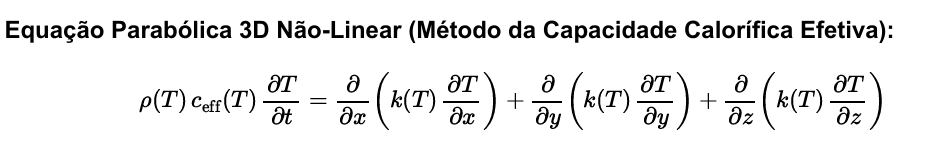

# 6.Condições de fronteira

Condições iniciais: T(x, y, z, 0) = T0 ≤ 0 ∘C (ex.: T0 = −10 ∘C ou − 5 ∘C)

Opção 1 (Robin): Convecção de calor com o ambiente quente: −k(T) ∂T ∂n = h (T − Tamb)

% Ver isto melhor
% Exemplo: substituir pelos IDs confirmados na figura
facesSimetria = [3 4];

% Faces exteriores expostas ao ambiente
facesConveccao = setdiff(1:6, facesSimetria);

% Convecção nas faces exteriores
applyBoundaryCondition(model, 'mixed', 'Face', facesConveccao, 'h', h, 'r', h*Tamb);

% Simetria nas faces de corte: fluxo normal nulo
applyBoundaryCondition(model, 'neumann', 'Face', facesSimetria, 'g', 0);

# 7.Resoluçao Numérica

# 8.Verificação

%TODO

Desenhar malha cubica